# Position and Attitude Control of a Quadcopter

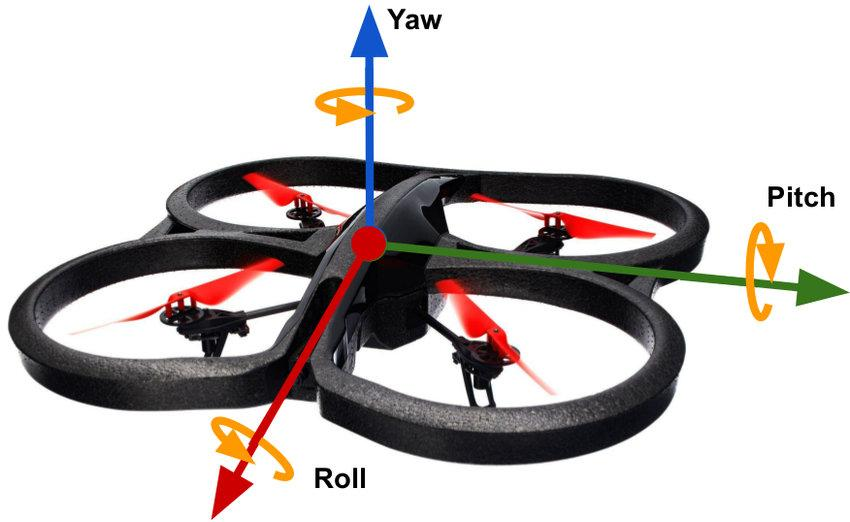

## Nomenclature

	Inertial frame								$\bar{N} = \{\hat{x}_N, \hat{y}_N, \hat{z}_N\}$

	Body frame								$\bar{B} = \{\hat{x}_B, \hat{y}_B, \hat{z}_B\}$

	Thrust constant							$K_t $

	Body mass								$mass \; [kg]$

	Gravity constant							$g \; [m/s^2]$

	Wing length								$l \; [m]$

	Inertia matrix								$I_b \; [kg m^2]$

	Propeller Thrust vector						$T_p$

	Propeller Torque vector						$\tau_p$

	Position vector							$r$

	Velocity vector 							$\dot{r}$

	Attitude of Body as DCM 					$R_{BN} = R_{NB}^T$

	Attitude of Body as Euler Angles	 			$q$

	Rotational velocity of Body w.r.t Inertial frame	$\omega$

*pre-superscript denotes the frame the vector is defined in.

## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
d = -1e-3 * diag([1 1 1.75]);

## Dynamics

let the torque kinematics (transform from input to angular acceleration) be $\tau_k = \pmatrix{1 & 0 & -1 & 0 \cr 0 & -1 & 0 & 1 \cr -1 & 1 & -1 & 1}$ 

Forces:

	
$$^NT_p = R_{NB}\;\hat{z}_{B}\; K_t \Sigma^4_{i=1}u_i^2$$


	
$$^B\tau_p = K_t \;l\;\tau_k\;u^Tu$$


	
$$^NF_g = -massg \hat{z}_N$$


	
$$^NF_w = w_1\hat{x}_N + w_2\hat{y}_N + w_3\hat{z}_N$$


	
$$^B\tau_w = g_1\hat{x}_N + g_2\hat{y}_N + g_3\hat{z}_N$$


	
$$^NF_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; ^N\dot{r}$$
 

	
$$^B\tau_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; \omega$$
 

Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w + F_d$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} = I_b^{-1}(-[\tilde{x_4}]\bar{I}x_4+\tau_p + \tau_w + \tau_d)$$


The dynamics can also be linearized about the zero-attitude and hover throttle


$$^NT_p = \hat{z}_{N}\; K_t \Sigma^4_{i=1}u_i$$



$$^B\tau_p = K_t \;l\;\tau_k u$$


Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} =I_b^{-1}(\tau_p + \tau_w + \tau_d)$$


As a state space model:

m = 4;			% number of inputs
n = 4;			% number of states 4 (vectors)
state_dim = 3;	% dimension of each state


z = [0; 0; 1];
Z = [z z z z];
I = eye(state_dim);
O = zeros(state_dim, state_dim);

tau_k = [1  0 -1  0;
	     0 -1  0  1;
		-1  1 -1  1];

A = [O I O O;						% block size (state_dim, state_dim)
	 O d O O;
	 O O O I;
	 O O O d];

O = zeros(state_dim, m);

B = Kt *[O; Z; O; l * tau_k];		% block size (state_dim, n_inputs) ignore non-controlled forces

C = eye(n * state_dim);
D = 0;


G = ss(A, B, C, D)

G =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1          0         0         0         1         0         0         0         0         0         0         0         0
   x2          0         0         0         0         1         0         0         0         0         0         0         0
   x3          0         0         0         0         0         1         0         0         0         0         0         0
   x4          0         0         0    -0.001         0         0         0         0         0         0         0         0
   x5          0         0         0         0    -0.001         0         0         0         0         0         0         0
   x6          0         0         0         0         0  -0.00175         0         0         0         0         0         0
   x7          0         0         0         0         0         0         0         0         0  

## Non Linear Control Law

[Kref, Kfb, Kff] = nonlinear_control_law(Kt, mass, g, [0; 0; 0]);
L = G * Kfb;
S = 1 / (eye(12) + L);
T = minreal(L * S);

28 states removed.



Hinf_norm_n11 = norm(T, 'inf')

Hinf_norm_n11 = 2.1951e+04

Hinf_norm_n22 = norm(T * Kref, 'inf')

Hinf_norm_n22 = 0

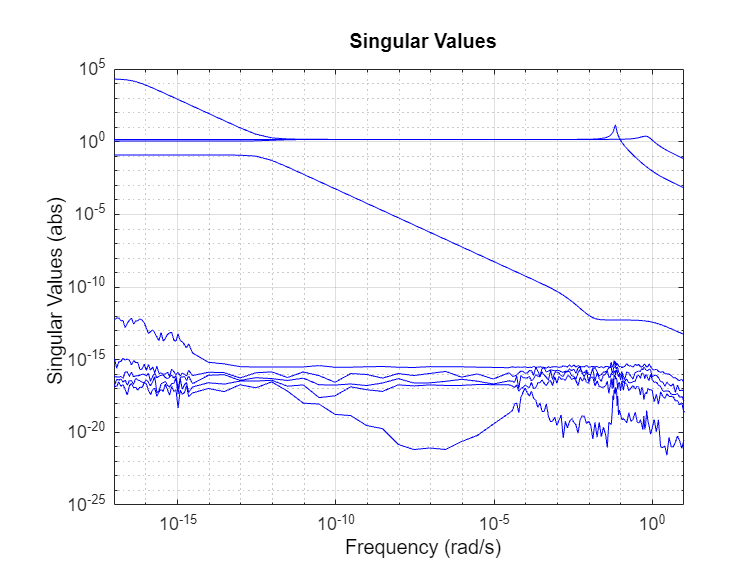


figure
h = sigmaplot(T, 'b');
setoptions(h,'MagUnits','abs');

## Analysis

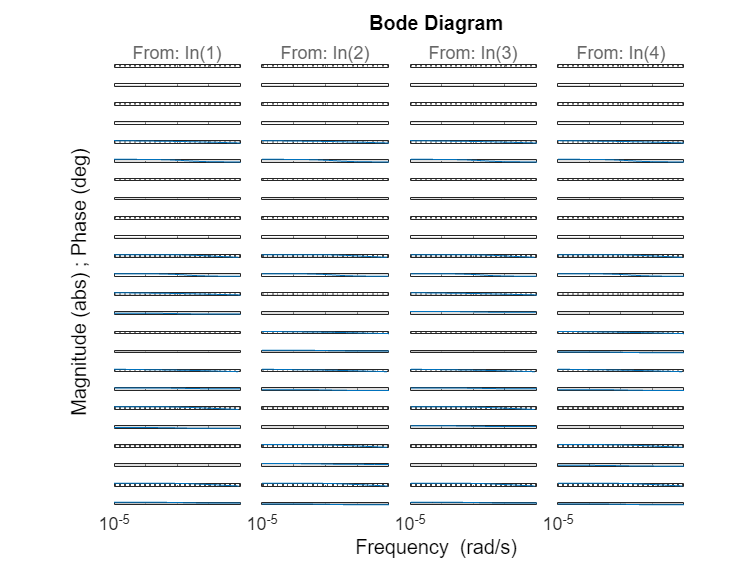

figure
bodeplot(G)

## Simulation

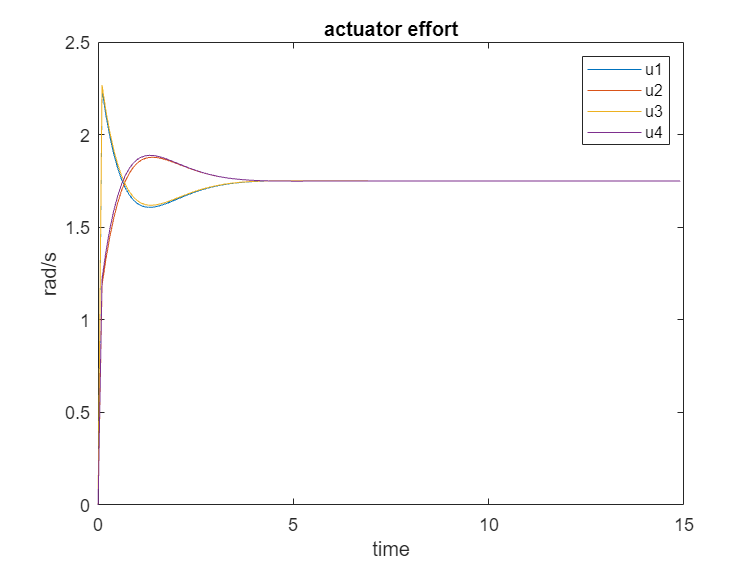

max_time = 15;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

qr_ext = [0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial condition
r_r = [0; 0; 0];
% r_hist(3, 1) = 1;
q_hist(1, 1) = -0.17;
q_hist(3, 1) = pi;
% omega_hist(1, 1) = -0.5;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(r_hist(:,i), rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib, d);

	% update states and control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = nonlinear_control_law(Kt, mass, g, q_hist(:,i));

	u_hist(:, i + 1) = Kff + (Kfb * ((Kref * R) - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = sign(q_hist(:, i) + (dq * dt)) .* mod(abs(q_hist(:, i) + (dq * dt)), 2 * pi);
	qr_hist(:, i + 1) = qr_ext * (Kref * R);
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	V = norm((Kref * R) - X);

	if V > 1e150
		fprintf("Breaking for %d at %i", V, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

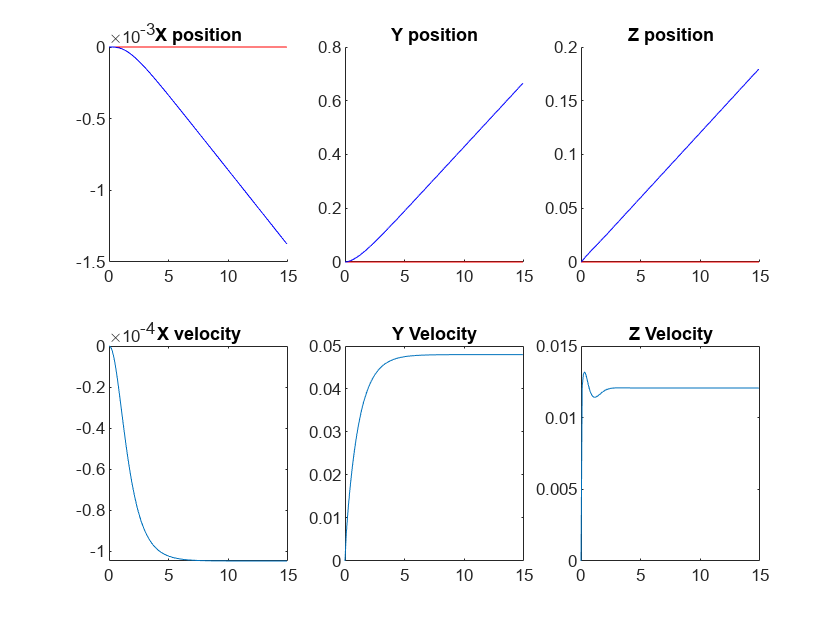


figure
title("Position history")
draw_position_history(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, 100);

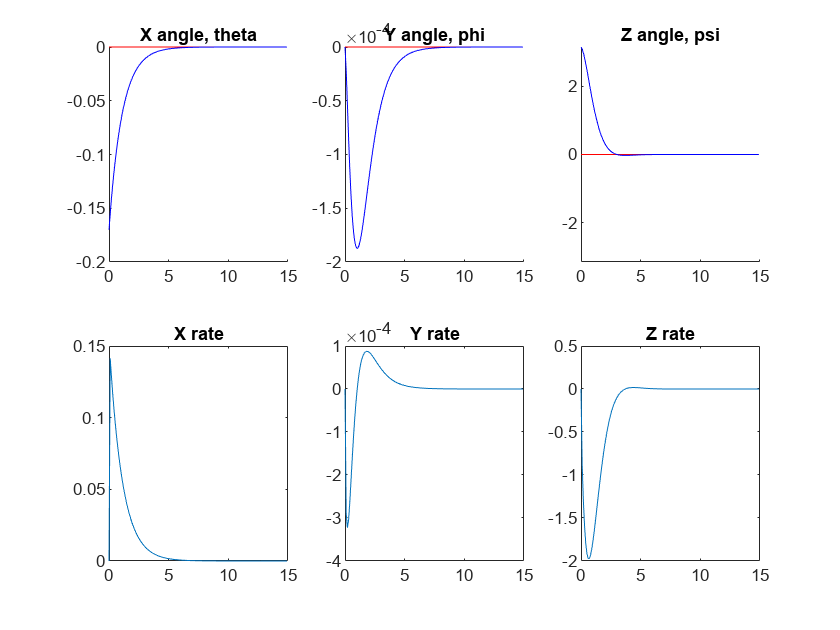


figure
title("Attitude history")
draw_attitude_history(t_space, q_hist, omega_hist, qr_hist, 100);

## Functions

function [Kref, Kfb, Kff] = nonlinear_control_law(Kt, m, g, q)
	n_inputs = 4;			% number of inputs
	state_dim = 3;			% dimension of each state
	tau_k = [1  0 -1  0;
	         0 -1  0  1;
		    -100  100 -100  100];

	z = [0; 0; 1];
	Z = [z z z z];
	I = eye(state_dim);
	O = zeros(state_dim, state_dim);

	hover_throttle = sqrt(g * m / (Kt * n_inputs)) * abs(cos(q(1)) * cos(q(2)));
	
	Katt = 100 * pinv(tau_k);
	Krate = 110 * pinv(tau_k);
	Kq = 0.0 * [0 1 0;
			   -1 0 0;
				0 0 0];
	Kzp = 0 * Z';
	Kzd = 0 * Z';
	Kref = [I O O O;
		    O O O O;
			Kq O O O;
			O O O O];
	Kfb = [Kzp Kzd Katt Krate];
	Kff = hover_throttle * ones(n_inputs, 1);
end

function draw_position_history(t_space, v1, v2, r_r, skip)
	subplot(2, 3, 1)
	hold on
	plot(t_space(1:skip:end), r_r(1, 1:skip:end), 'r')
	plot(t_space(1:skip:end), v1(1, 1:skip:end), 'b')
	title("X position")
	
	subplot(2, 3, 4)
	plot(t_space(1:skip:end), v2(1, 1:skip:end))
	title("X velocity")
	
	subplot(2, 3, 2)
	hold on
	plot(t_space(1:skip:end), r_r(2, 1:skip:end), 'r')
	plot(t_space(1:skip:end), v1(2, 1:skip:end), 'b')
	title("Y position")

	subplot(2, 3, 5)
	plot(t_space(1:skip:end), v2(2, 1:skip:end))
	title("Y Velocity")

	subplot(2, 3, 3)
	hold on
	plot(t_space(1:skip:end), r_r(3, 1:skip:end), 'r')
	plot(t_space(1:skip:end), v1(3, 1:skip:end), 'b')
	title("Z position")

	subplot(2, 3, 6)
	plot(t_space(1:skip:end), v2(3, 1:skip:end))
	title("Z Velocity")
end

function draw_attitude_history(t_space, v1, v2, q_r, skip)
	subplot(2, 3, 1)
	hold on
	plot(t_space(1:skip:end), q_r(1, 1:skip:end), 'r')
	plot(t_space(1:skip:end), v1(1, 1:skip:end), 'b')
% 	ylim([-pi, pi])
	title("X angle, theta")
	
	subplot(2, 3, 4)
	plot(t_space(1:skip:end), v2(1, 1:skip:end))
	title("X rate")
	
	subplot(2, 3, 2)
	hold on
	plot(t_space(1:skip:end), q_r(2, 1:skip:end), 'r')
	plot(t_space(1:skip:end), v1(2,1:skip:end), 'b')
% 	ylim([-pi, pi])
	title("Y angle, phi")

	subplot(2, 3, 5)
	plot(t_space(1:skip:end), v2(2, 1:skip:end))
	title("Y rate")

	subplot(2, 3, 3)
	hold on
	plot(t_space(1:skip:end), q_r(3, 1:skip:end), 'r')
	plot(t_space(1:skip:end), v1(3, 1:skip:end), 'b')
	ylim([-pi, pi])
	title("Z angle, psi")

	subplot(2, 3, 6)
	plot(t_space(1:skip:end), v2(3, 1:skip:end))
	title("Z rate")
end

function [dr, ddr, dq, do] = Rufous_Dynamics(r, rdot, q, omega, u, Kt, m, g, l, I, d)
	% constrain the input to a feasble one
	u = max(u, [0; 0; 0; 0]);

	dr = rdot;
	ddr = Rufous_Thrust(q, u, Kt) - [0; 0; m * g] ;

	dq = omega;
	do = I^-1 * (-tilde_op(omega) * I * omega + Rufous_Torque(u, Kt, l));
end

function Tp = Rufous_Thrust(q, u, Kt)
	Rnb = euler_angles_to_dcm(-q);
	z_hat_b = Rnb \ [0; 0; 1];
	Tp = Kt * sum(u.^2) * z_hat_b;
end

function Taup = Rufous_Torque(u, Kt, l)
	Taup = Kt * l * [1 0 -1 0; 0 -1 0 1; -1 1 -1 1] * u.^2;
end

function DCM = euler_angles_to_dcm(q)
	Rx = [1 0 0; 0 cos(q(1)) -sin(q(1)); 0 sin(q(1)) cos(q(1))];
	Ry = [cos(q(2)) 0 sin(q(2)); 0 1 0; -sin(q(2)) 0 cos(q(2))];
	Rz = [cos(q(3)) -sin(q(3)) 0; sin(q(3)) cos(q(3)) 0; 0 0 1];
	DCM = Rz * Ry * Rx;
end

function m = tilde_op(v)
	m = [0 -v(3) v(2); v(3) 0 -v(1); -v(2) v(1) 0];
end